%Joseph Dearing
function matrixsquare(L,N,beta,n) %Length,#postions,beta,#repititions
%for simplicity m=h=1
xvec=linspace(-L,L,N)';
dx=2*L/(N-1);
[x,xdash]=meshgrid(xvec,xvec);
%trotter approximate of p with V(x)=1/2 * x^2
pfree=sqrt(1/(2*pi*beta))*exp(-(x-xdash).^2/(2*beta));
e1=exp(-0.5*beta*(0.5*x.^2));
e2=exp(-0.5*beta*(0.5*xdash.^2));
p1=e1.*pfree.*e2;
%incorperates both for loops of algorithm, repeats n times
for i = 1:n
    p1=dx*(p1*p1);
end
betaf=beta*2^n;
p1diag=diag(p1);
pdiagexact=sqrt(1/(2*pi*sinh(betaf)))*exp(-xvec.^2*tanh(betaf/2)); %diagonal density matrix of eq 6.24
figure;
hold on;
plot(xvec,p1diag,'r-','LineWidth',2)
plot(xvec,pdiagexact,'b--','LineWidth',1)
legend('Computed', 'Exact');
xlabel('Position (x)');
ylabel('p(x,x,beta)');
title(['V(x)=1/2*x^2, beta=',num2str(betaf)]);
end

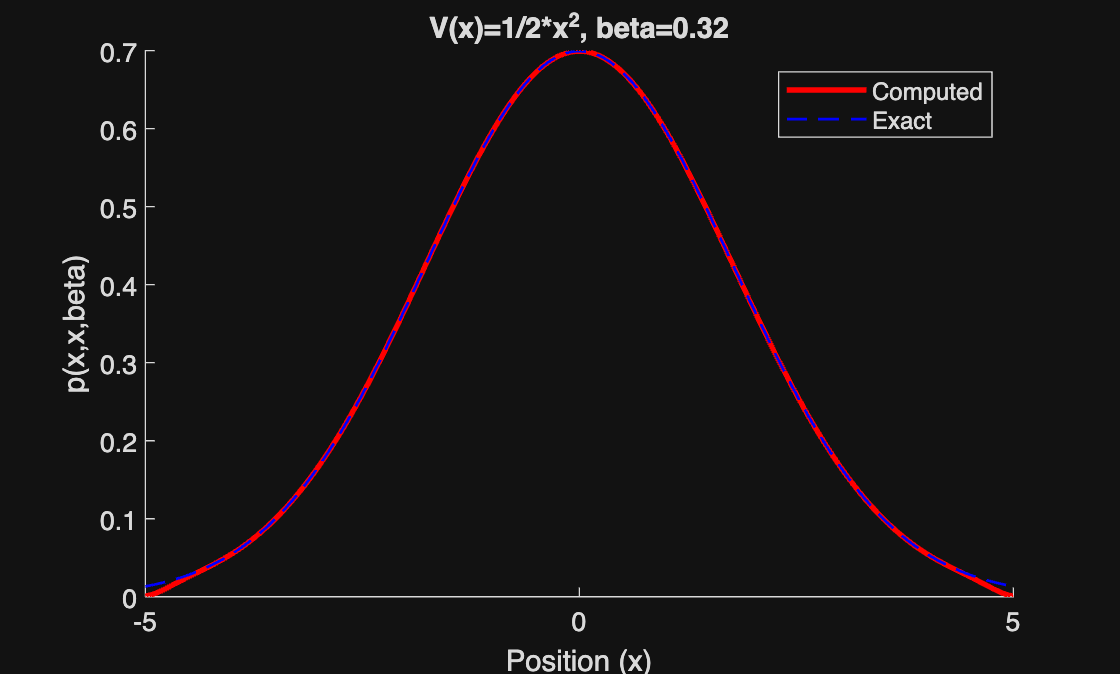

matrixsquare(5,300,0.01,5)

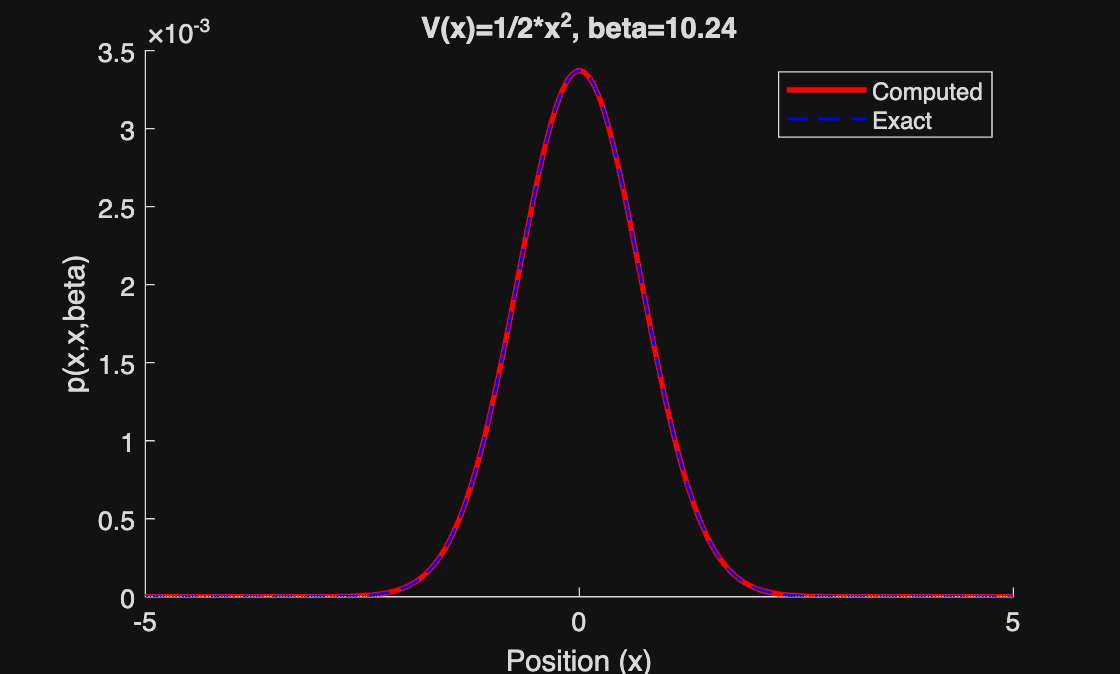

matrixsquare(5,300,0.01,10)

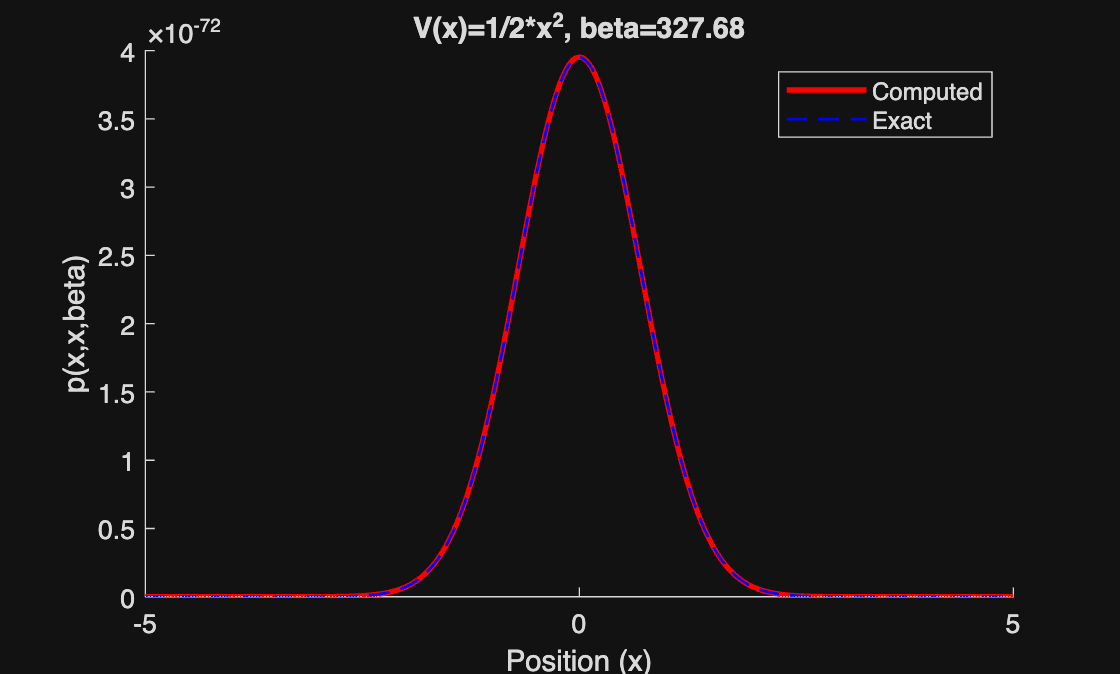

matrixsquare(5,300,0.01,15)

We can see that for various temperatures, we recover the diagonal density matrix of eq 6.24 (beta = 1/kB*T)

function matrixsquare2(L,N,beta,n) %Length,#postions,beta,#repititions
%for simplicity m=h=1
xvec=linspace(-L,L,N)';
dx=2*L/(N-1);
[x,xdash]=meshgrid(xvec,xvec);
%trotter approximate of p with V(x)=1/2 * x^2 + 1/4 * x^4
pfree=sqrt(1/(2*pi*beta))*exp(-(x-xdash).^2/(2*beta));
e1=exp(-0.5*beta*(0.5*x.^2+0.25*x.^4));
e2=exp(-0.5*beta*(0.5*xdash.^2+0.25*xdash.^4));
p1=e1.*pfree.*e2;
%incorperates both for loops of algorithm, repeats n times
for i = 1:n
    p1=dx*(p1*p1);
end
betaf=beta*2^n;
p1diag=diag(p1);
figure;
plot(xvec,p1diag,'r-','LineWidth',2)
xlabel('Position (x)');
ylabel('p(x,x,beta)');
title(['V(x)=1/2*x^2+1/4*x^4, beta=',num2str(betaf)]);
end

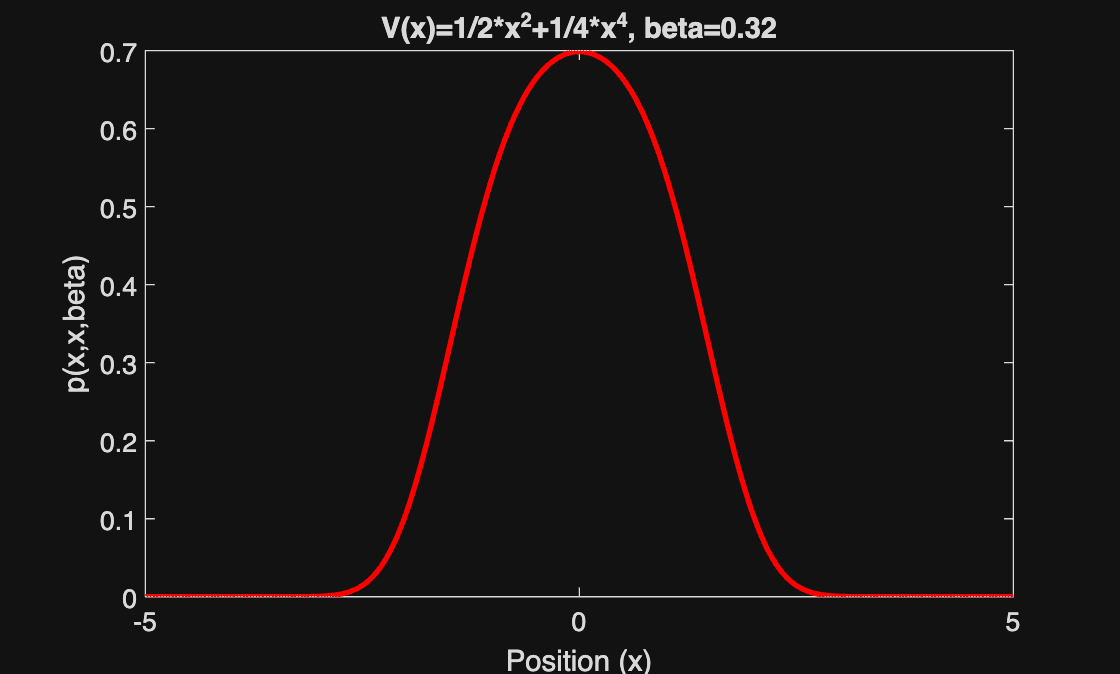

matrixsquare2(5,300,0.01,5)